ESCALÓN RR

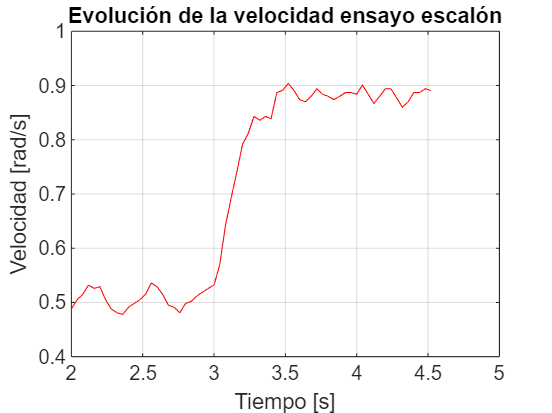

escalon=[
2.000 78 15.015 0.488
2.040 78 15.540 0.505
2.080 78 15.855 0.515
2.120 78 16.380 0.532
2.160 78 16.170 0.526
2.200 78 16.275 0.529
2.240 78 15.540 0.505
2.280 78 15.015 0.488
2.320 78 14.805 0.481
2.360 78 14.700 0.478
2.400 78 15.120 0.491
2.440 78 15.330 0.498
2.480 78 15.540 0.505
2.520 78 15.855 0.515
2.560 78 16.485 0.536
2.600 78 16.275 0.529
2.640 78 15.855 0.515
2.680 78 15.225 0.495
2.720 78 15.120 0.491
2.760 78 14.805 0.481
2.800 78 15.330 0.498
2.840 78 15.435 0.502
2.880 78 15.750 0.512
2.920 78 15.960 0.519
2.960 78 16.170 0.526
3.000 150 16.380 0.532
3.040 150 17.535 0.570
3.080 150 19.739 0.642
3.120 150 21.314 0.693
3.160 150 22.785 0.741
3.200 150 24.360 0.792
3.240 150 24.989 0.812
3.280 150 25.934 0.843
3.320 150 25.725 0.836
3.360 150 25.935 0.843
3.400 150 25.829 0.839
3.440 150 27.300 0.887
3.480 150 27.405 0.891
3.520 150 27.824 0.904
3.560 150 27.405 0.891
3.600 150 26.880 0.874
3.640 150 26.775 0.870
3.680 150 27.090 0.880
3.720 150 27.509 0.894
3.760 150 27.195 0.884
3.800 150 27.089 0.880
3.840 150 26.879 0.874
3.880 150 27.090 0.880
3.920 150 27.300 0.887
3.960 150 27.300 0.887
4.000 150 27.195 0.884
4.040 150 27.720 0.901
4.080 150 27.195 0.884
4.120 150 26.670 0.867
4.160 150 27.089 0.880
4.200 150 27.510 0.894
4.240 150 27.509 0.894
4.280 150 26.984 0.877
4.320 150 26.459 0.860
4.360 150 26.775 0.870
4.400 150 27.299 0.887
4.440 150 27.299 0.887
4.480 150 27.509 0.894
4.520 150 27.405 0.891
];

t = escalon(:,1);
refPWM = escalon(:,2);
u = refPWM - refPWM(1); %Entrada del System Identification
w    = escalon(:,3);
vel = escalon(:,4);
y = vel - vel(1); %Salida del System Identification

figure
plot(t, vel, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad ensayo escalón');
grid on;

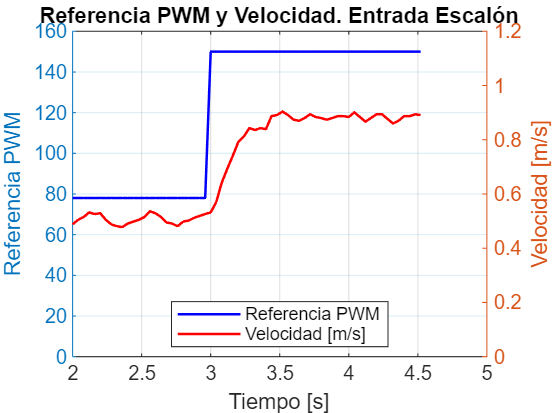


figure;
% Eje izquierdo (referencia PWM)
yyaxis left
p1 = plot(t, refPWM, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 160]);                 % límites del eje izquierdo
ylabel('Referencia PWM');

% Eje derecho (velocidad)
yyaxis right
p2 = plot(t, vel, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 1.2]);                    % límites del eje derecho
ylabel('Velocidad [m/s]');

xlabel('Tiempo [s]');
title('Referencia PWM y Velocidad. Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','best');

RESPUESTA AL ESCALÓN EN BUCLE ABIERTO

figure
G=tf(tf1) %cargamos nuestro modelo de System Identification


G =
 
  From input "u1" to output "y1":
     0.001026
  ---------------
  1 - 0.8167 z^-1
 
Name: tf1
Sample time: 0.04 seconds
Discrete-time transfer function.
Model Properties


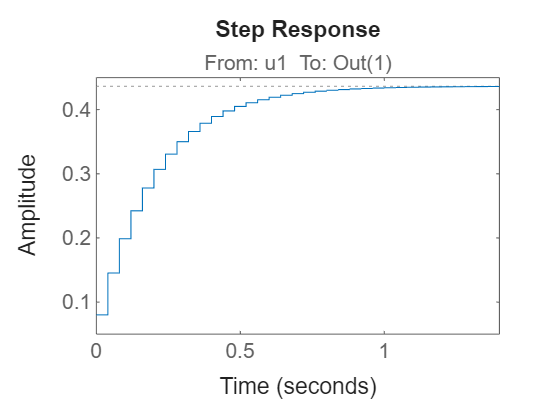

step(78*G) %Vemos la respuesta ante entrada escalón

OBTENCIÓN DE LOS CONTROLADORES PID

figure
%Ajuste manual PID
Kp = 500; Ki = 19000; Kd = 0.0; Ts=0.04;
Cd = pid(Kp, Ki, Kd, 'Ts', Ts)
T = feedback(Cd*G,1);
step(0.386*T)
xlim([0 2]);
grid on

%Hago el controlador con el PID Tuner
%Valores obtenidos con la APP PID Tuner
Kp_tuner = 159.7;
Ki_tuner = 1078;
Kd_tuner = 0;
Ts = 0.04;         

% Crear el controlador discreto
Cd_tuner = pid(Kp_tuner, Ki_tuner, Kd_tuner, 'Ts', Ts)


Cd_tuner =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 160, Ki = 1.08e+03, Ts = 0.04
 
Sample time: 0.04 seconds
Discrete-time PI controller in parallel form.
Model Properties


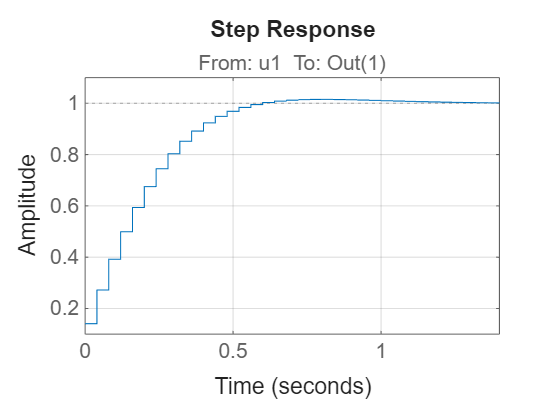

T_tuner=feedback(Cd_tuner*G,1);
step(1*T_tuner)
grid on

Resultados control PID Tuner

escalonPID_Tuner = [

];


t3 = escalonPID_Tuner(:,1);
refvel3 = escalonPID_Tuner(:,2);
refPWM3 = escalonPID_Tuner(:,3);
vel3    = escalonPID_Tuner(:,4);

figure
plot(t3, vel3, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad con ensayo escalón y PID hallado con PID Tuner');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t3, refvel3, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t3, vel3, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','best');

Resultados control PID Manual

escalonPID_Manual=[
    ];

t4 = escalonPID_Manual(:,1);
refPWM4 = escalonPID_Manual(:,2);
vel4    = escalonPID_Manual(:,3);

figure
plot(t4, vel4, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Ensayo escalón con PID con ajuste manual');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t4, refPWM4, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 25]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t4, vel4, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 24]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [rad/s]'}, 'Location','best');

